Q5

for n=2:12
    x=ones(n);
    x=x(:,1);
    H=hilb(n);
    b=H*x;
    x0=(GaussElimPartPivot(H,b))';
    r=b-H*x0;
    xdiff=x-x0;
    y1(n-1)=log10(norm(xdiff, "inf"));
    y2(n-1)=log10(cond(H));
    disp(norm(r, "inf"))
end

result =     1.0000    1.0000


   1.1102e-16



result =     1.0000    1.0000    1.0000


   2.2204e-16



result =     1.0000    1.0000    1.0000    1.0000


     0



result =     1.0000    1.0000    1.0000    1.0000    1.0000


   4.4409e-16



result =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


   2.2204e-16



result =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


   4.4409e-16



result =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


   4.4409e-16



result =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


   2.2204e-16



result =     1.0000    1.0000    1.0000    1.0000    0.9999    1.0002    0.9997    1.0003    0.9998    1.0000


   8.8818e-16



result =     1.0000    1.0000    1.0000    1.0002    0.9991    1.0033    0.9929    1.0097    0.9920    1.0037    0.9993


   2.2204e-16



result =     1.0000    1.0000    0.9999    1.0019    0.9862    1.0604    0.8319    1.3040    0.6439    1.2607    0.8917    1.0195


   2.2204e-16




y1=y1(1:11)

y1 =   -15.1764  -14.0003  -12.2137  -12.2098   -9.2790   -7.5908   -6.3780   -4.7082   -3.4971   -2.0151   -0.4484


y2=y2(1:11)

y2 =     1.2851    2.7194    4.1907    5.6782    7.1747    8.6770   10.1835   11.6930   13.2048   14.7177   16.2098


n=2:12

n =      2     3     4     5     6     7     8     9    10    11    12


subplot(1,2,1)
p1=plot(n, y1, 'm-')

p1 =   Line with properties:

              Color: [1 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2 3 4 5 6 7 8 9 10 11 12]
              YData: [-15.1764 -14.0003 -12.2137 -12.2098 -9.2790 -7.5908 -6.3780 -4.7082 -3.4971 -2.0151 -0.4484]
              ZData: [1×0 double]

  Show all properties


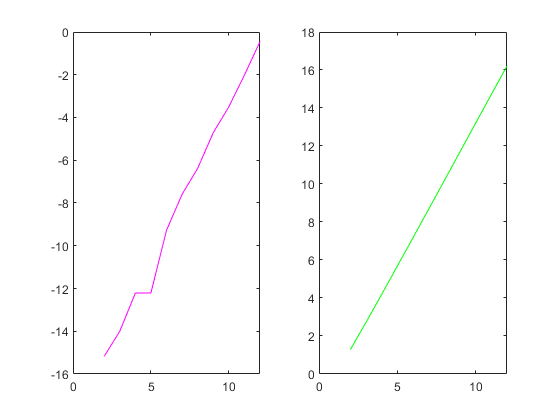

p2 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2 3 4 5 6 7 8 9 10 11 12]
              YData: [1.2851 2.7194 4.1907 5.6782 7.1747 8.6770 10.1835 11.6930 13.2048 14.7177 16.2098]
              ZData: [1×0 double]

  Show all properties


subplot(1,2,2)
p2=plot(n, y2, 'g-')